# Подавление шума с помощью алгоритма RLS

#### Загрузка музыкального отрезка, внешнего шума, коэффициентов фильтра нижних частот:

clc;
close all;
clear all;
[whistle,fs] = audioread('whistle.mp3');
debussy = audioread('debussy.mp3');
debussy = debussy(1:length(whistle));
load FIR_lowpass.mat;
noisy = debussy + FIR_lowpass(whistle);


#### Инициализация параметров RLS-фильтра

[g2,fs] = audioread('whistle.mp3'); % g2 - шум
[s,fs] = audioread('debussy.mp3');% s - чистый сигнал
[x,fs] = audioread("noisy.wav");% - x - смешанный сигнал

#### График шума

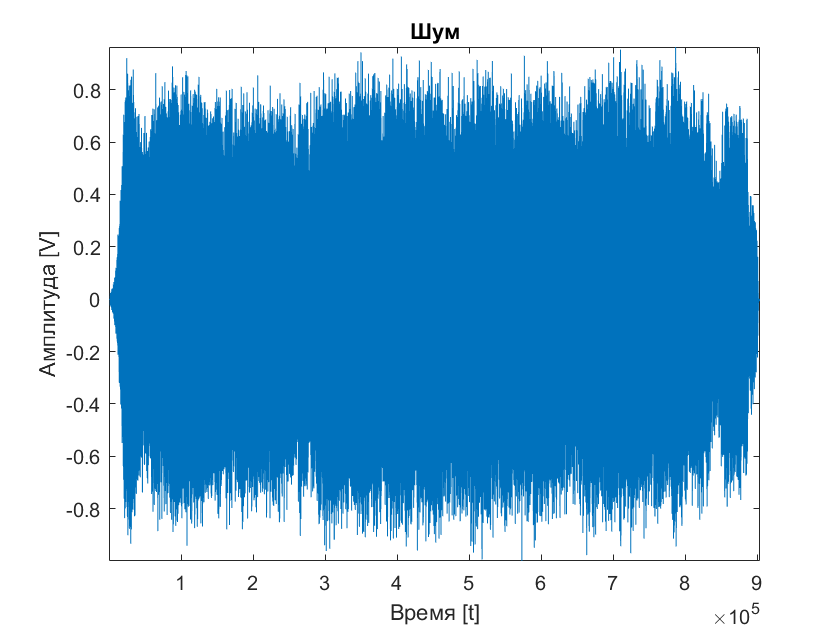

figure, plot(g2);
xlabel('Время [t]');
ylabel('Амплитуда [V]');
title ('Шум');
axis tight;

#### График сигнала

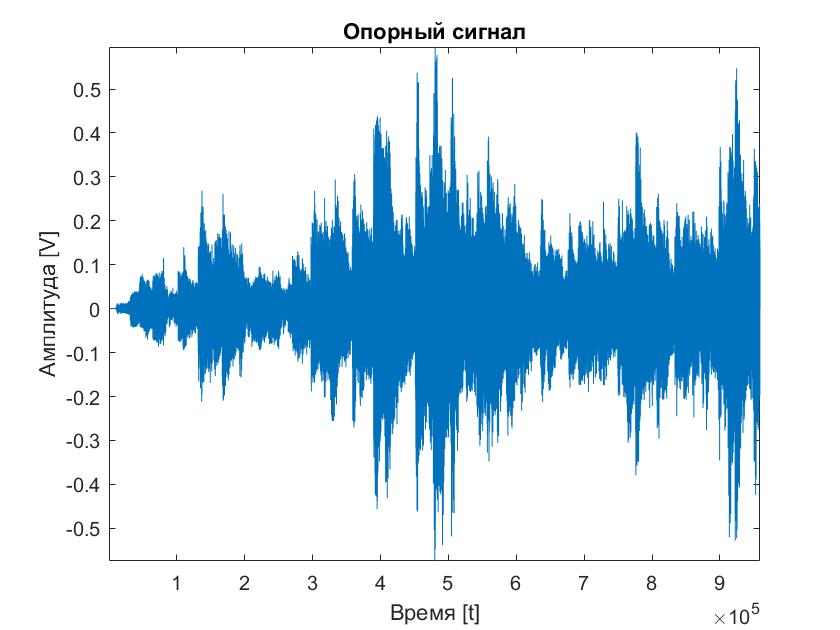

figure, plot(s);
xlabel('Время [t]');
ylabel('Амплитуда [V]');
title ('Опорный сигнал');
axis tight;

#### График смешанного сигнала

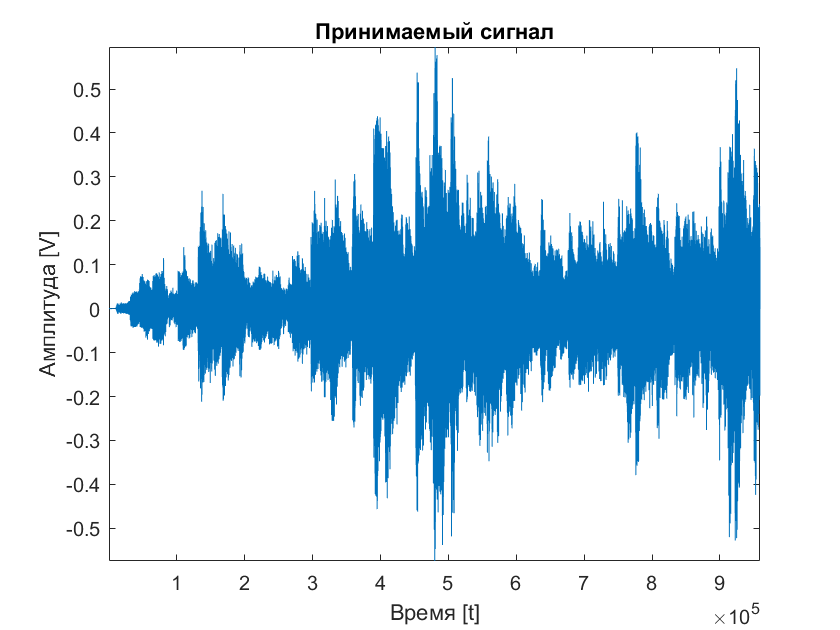

figure, plot(s);
xlabel('Время [t]');
ylabel('Амплитуда [V]');
title ('Принимаемый сигнал');
axis tight;

#### Параметры фильтра RLS

M = 7;
lambda = 1;
lambdainv = 1/lambda;
delta = 5;
deltainv = 1/delta;

#### Инифиализация RLS-фильтра

N = length(x);
w = zeros(M,1);
P = deltainv*eye(M);
e = zeros(N,1);

#### Реализация RLS-алгоритма

g2 = g2(:);
x = x(:);
m=0;

for i=M:N
    y = g2(i:-1:i-M+1);
    e(i) = x(i)-w'*y;
    k = (P*y)/(lambda+y'*P*y);
    P = (P - k*y'*P)*lambdainv;
    w = w + k+e(i);
    m=m+1;
    w1(M,:)=w(:,1);
end
e = normalize(e,'range',[-1 1]);

#### Графики сигналов

fprintf('Количество итераций равно %d\n',m);

Количество итераций равно 903786


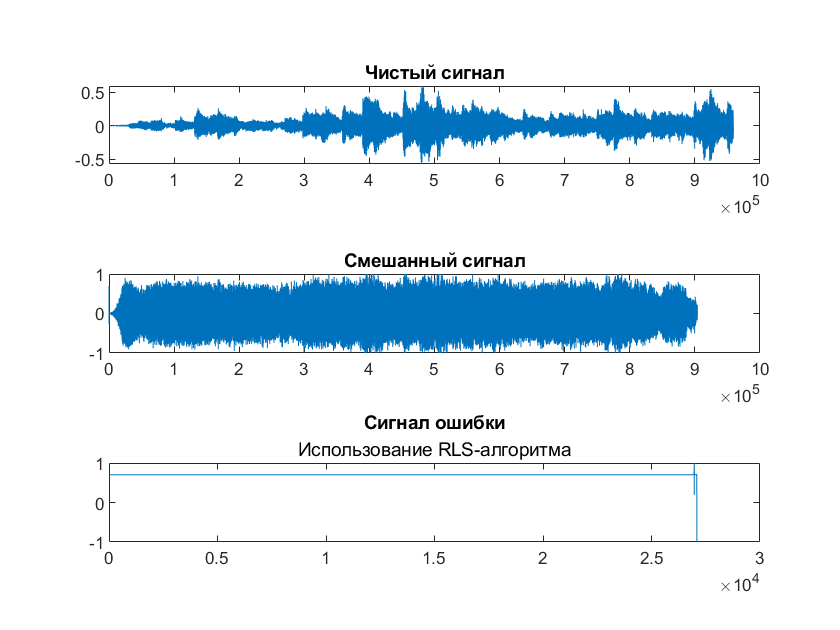

figure,
subplot(3,1,1),plot(s);title('Чистый сигнал');
subplot(3,1,2),plot(x);title('Смешанный сигнал');
subplot(3,1,3),plot(e);title('Сигнал ошибки');
subtitle('Использование RLS-алгоритма');

#### Результат работы алгоритма RLS-фильтра

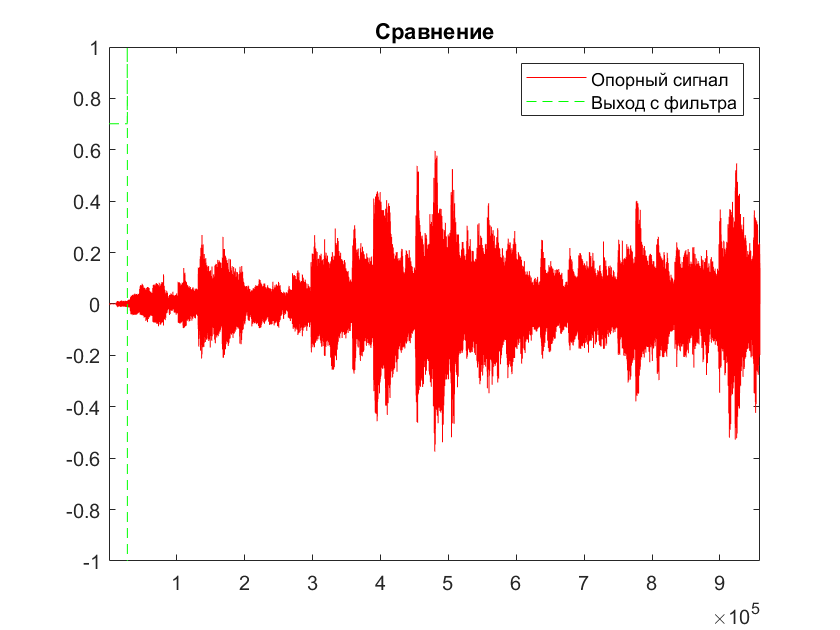

figure,
plot(s,'r');
hold on;
plot(e,'--g');
title('Сравнение');
legend('Опорный сигнал','Выход с фильтра');
axis tight;

#### КФ

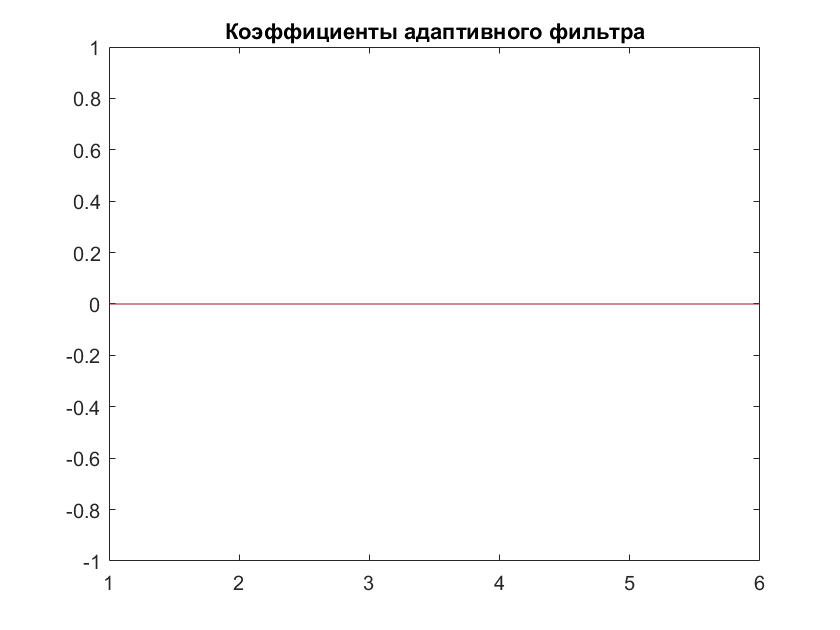

figure,
plot(w1);
title('Коэффициенты адаптивного фильтра');
axis tight;